
clear all;
close all;

save_data = 1;
maindir = '\\Artemis-pc\Data\2026-06-03\';
x = [0:1:20]*13.7;
%x = [18 30 43 55 69 82 ...
%    96 109 123 135 148 ...
%    161 176 189 205 222 ...
%    237 252 270 288 301 ...
%    323 336 352 366 380];   % um
y = [75 75 75 75 75 75 ...
    75 75 75 74 73 ...
    68 53 26 6 1 ...
    1 1 1 1 1];

xmin = min(x);
xmax = max(x);
ymin = 0;
ymax = max(y)*1.1;

%load('\\Artemis-pc\Data\2026-06-02\A_M1.mat');


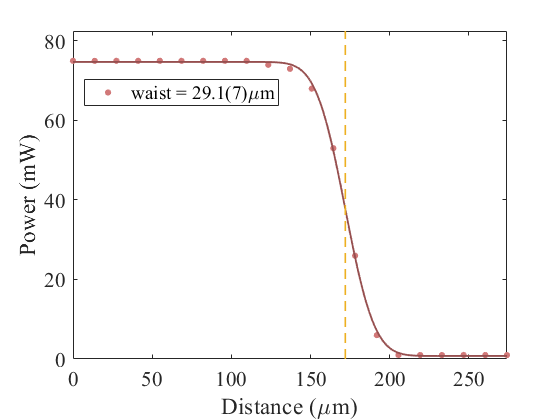


%% 拟合: '无标题拟合 1'。
[xData, yData] = prepareCurveData( x, y );

% 设置 fittype 和选项。
ft = fittype( 'a*erf(sqrt(2)*(x-u)/w)+c', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [30 30 150 10];   % a c u w
opts.Lower = [-100 -100 0 0];   % a c u w

% 对数据进行模型拟合。
[fitresult, gof] = fit( xData, yData, ft, opts );
u = fitresult.u;
w = fitresult.w;
interval = confint(fitresult);
us = (interval(2,3)-interval(1,3))/4;
ws = (interval(2,4)-interval(1,4))/4;

% 绘制数据拟合图。
f1 = figure; hold on;
l1 = plot( fitresult, xData, yData );   % [点 线]
l1(1).MarkerSize = 16;
l1(1).Color = [0.82 0.47 0.47];
l1(2).LineWidth = 1.4;
l1(2).Color = [0.59 0.31 0.31];

l2 = plot([u u],[ymin ymax],'--','Color',[0.93,0.69,0.13],'LineWidth',1.2);

xlim([xmin xmax]);
ylim([ymin ymax]);

xlabel( 'Distance (\mum)' );
ylabel('Power (mW)');
legend(['waist = ',num2str(w,'%.1f'),'(',num2str(ws*1e1,'%.0f'),')','\mum'],'','',...
    'Location','best');
grid off;
box on;

set(gca,'FontSize',16,'FontName','Times New Roman');
set(f1,'Visible','on');


if save_data == 1
    savefig(f1,[maindir,'A_M.fig']);
    saveas(f1,[maindir,'A_M.png']);
    %
    save([maindir,'A_M.mat']);
end